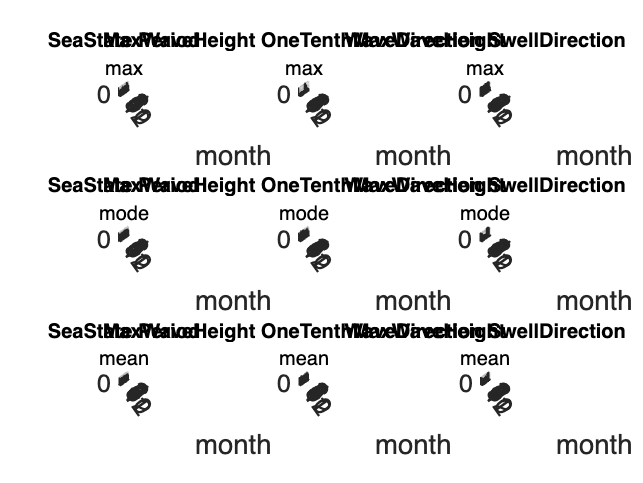

%sea state 0-9 Grade 1
%wave direction degree 2 3 4
%swell direction degree 5 6 7
%Max wave height **.* m 8 9 10
%one-tenth max wave height **.* m  11 12 13
%Period **.* s 14 15 16
MM1=[];
MM2=[];
MM3=[];
for k = 0:11
    if k==0
                  SeaState = MS(1:Ml(1),1);
             WaveDirection = MS(1:Ml(1),2).*100+MS(1:Ml(1),3).*10+MS(1:Ml(1),4).*1;
                       WaveDirection(WaveDirection>996) = []; % delete number that lager than 996
            SwellDirection = MS(1:Ml(1),5).*100+MS(1:Ml(1),6).*10+MS(1:Ml(1),7).*1;
                     SwellDirection(SwellDirection>996) = [];
             MaxWaveHeight = MS(1:Ml(1),8).*10+ MS(1:Ml(1),9).*1+ MS(1:Ml(1),10).*0.1;
                      MaxWaveHeight(MaxWaveHeight>99.6) = [];
    OneTenthMaxWaveHeight = MS(1:Ml(1),11).*10+MS(1:Ml(1),12).*1+MS(1:Ml(1),13).*0.1;
    OneTenthMaxWaveHeight(OneTenthMaxWaveHeight>99.6) = [];
                    Period = MS(1:Ml(1),14).*10+MS(1:Ml(1),15).*1+MS(1:Ml(1),16).*0.1;
                                    Period(Period>99.6) = [];
    else
                  SeaState = MS(Ml(k)+1:Ml(k+1),1);
             WaveDirection = MS(Ml(k)+1:Ml(k+1),2).*100+MS(Ml(k)+1:Ml(k+1),3).*10+MS(Ml(k)+1:Ml(k+1),4).*1;
                       WaveDirection(WaveDirection>996) = []; % delete number that lager than 996
            SwellDirection = MS(Ml(k)+1:Ml(k+1),5).*100+MS(Ml(k)+1:Ml(k+1),6).*10+MS(Ml(k)+1:Ml(k+1),7).*1;
                     SwellDirection(SwellDirection>996) = [];
             MaxWaveHeight = MS(Ml(k)+1:Ml(k+1),8).*10+ MS(Ml(k)+1:Ml(k+1),9).*1+ MS(Ml(k)+1:Ml(k+1),10).*0.1;
                      MaxWaveHeight(MaxWaveHeight>99.6) = [];
    OneTenthMaxWaveHeight = MS(Ml(k)+1:Ml(k+1),11).*10+MS(Ml(k)+1:Ml(k+1),12).*1+MS(Ml(k)+1:Ml(k+1),13).*0.1;
    OneTenthMaxWaveHeight(OneTenthMaxWaveHeight>99.6) = [];
                    Period = MS(Ml(k)+1:Ml(k+1),14).*10+MS(Ml(k)+1:Ml(k+1),15).*1+MS(Ml(k)+1:Ml(k+1),16).*0.1;
                                 Period(Period>99.6) = [];
    end 
    WaveDirection=WaveDirection.*3.1416/180;
    SwellDirection=SwellDirection.*3.1416/180;    
    w1=max(SeaState); % max value
    w2=max(WaveDirection);
    w3=max(SwellDirection);
    w4=max(MaxWaveHeight);
    w5=max(OneTenthMaxWaveHeight);
    w6=max(Period);
    w11=mode(SeaState); %mode value
    w12=mode(WaveDirection);
    w13=mode(SwellDirection);
    w14=mode(MaxWaveHeight);
    w15=mode(OneTenthMaxWaveHeight);
    w16=mode(Period);
    w21=mean(SeaState); %mean value
    w22=mean(WaveDirection);
    w23=mean(SwellDirection);
    w24=mean(MaxWaveHeight);
    w25=mean(OneTenthMaxWaveHeight);
    w26=mean(Period);
    % every month max mode mean value
    MM1 = [MM1;w1 w6;w11 w16;w21 w26];
    MM2 = [MM2;w4 w5;w14 w15;w24 w25];
    MM3 = [MM3;w2 w3;w12 w13;w22 w23];
end

m11=MM1(1:3:36,:);
m12=MM2(1:3:36,:);
m13=MM3(1:3:36,:);

m21=MM1(2:3:36,:);
m22=MM2(2:3:36,:);
m23=MM3(2:3:36,:);

m31=MM1(3:3:36,:);
m32=MM2(3:3:36,:);
m33=MM3(3:3:36,:);
% characteristic= SeaState WaveDirection SwellDirection 
% MaxWaveHeight OneTenthMaxWaveHeight  Period

figure()
subplot(331)
bar3(m11)
view(35,30)
xlabel('SS Pd');ylabel('month');zlabel('value');
title("SeaState Period","max","FontSize",8)
subplot(332)
bar3(m12)
view(35,30)
xlabel('MH OH');ylabel('month');zlabel('m');
title("MaxWaveHeight OneTenthMaxWaveHeight","max","FontSize",8)
subplot(333)
bar3(m13)
view(35,30)
xlabel('WD SD');ylabel('month');zlabel('rad');
title("WaveDirection SwellDirection","max","FontSize",8)
subplot(334)
bar3(m21)
view(35,30)
xlabel('SS Pd');ylabel('month');zlabel('value');
title("SeaState Period","mode","FontSize",8)
subplot(335)
bar3(m22)
view(35,30)
xlabel('MH OH');ylabel('month');zlabel('m');
title("MaxWaveHeight OneTenthMaxWaveHeight","mode","FontSize",8)
subplot(336)
bar3(m23)
view(35,30)
xlabel('WD SD');ylabel('month');zlabel('rad');
title("WaveDirection SwellDirection","mode","FontSize",8)
subplot(337)
bar3(m31)
view(35,30)
xlabel('SS Pd');ylabel('month');zlabel('value');
title("SeaState Period","mean","FontSize",8)
subplot(338)
bar3(m32)
view(35,30)
xlabel('MH OH');ylabel('month');zlabel('m');
title("MaxWaveHeight OneTenthMaxWaveHeight","mean","FontSize",8)
subplot(339)
bar3(m33)
view(35,30)
xlabel('WD SD');ylabel('month');zlabel('rad');
title("WaveDirection SwellDirection","mean","FontSize",8)